clear all

load 'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Indexes\CA1\NormalizedIndexesTable.mat'; %The matrix obtained from the fuction ExtractMatFiles.m

rangoY = [0 30]; % Y-axis range

%SI
figure
%Create histogram
scatter(NormalizedIndexesTable.SI1,NormalizedIndexesTable.SI2,'filled', 'MarkerFaceColor','#990033');
xlim([-1 1]);
ylim([-1 1]);
title('SI CA1');
xlabel('SI F1');
ylabel('SI F2');

%Calculating the mean and error
SI_Mean = mean([NormalizedIndexesTable.SI1;NormalizedIndexesTable.SI2])

SI_Mean = 0.0535

SI_std = std([NormalizedIndexesTable.SI1;NormalizedIndexesTable.SI2]);
err_SI = SI_std / sqrt((size([NormalizedIndexesTable.SI1;NormalizedIndexesTable.SI2],1))*2)

err_SI = 0.0153

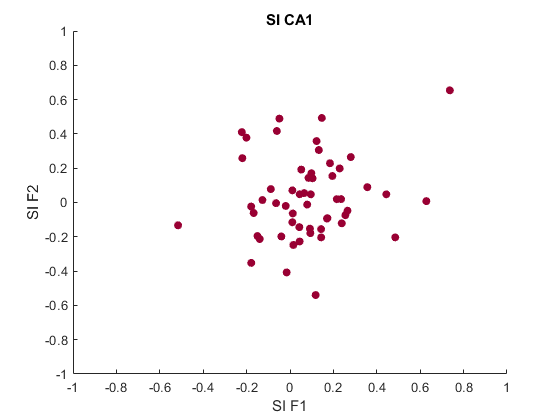


%Save figure
cd 'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Indexes\CA1\SI'
saveas(gcf,'SI_CA1.pdf');
saveas(gcf,'SI_CA1.tif');

saveas(gcf,'SI_CA1.fig');

% CSI
figure
%Create histogram
histogram(NormalizedIndexesTable.CSI,'BinWidth',0.1, 'FaceColor','#990033','FaceAlpha',1);
xlim([-1 1]);
ylim(rangoY);
xline(0,'LineWidth',2);
title('CSI');
xlabel('CSI index');
ylabel('repetitions');

%Calculating the mean and error
CSI_Mean = mean(NormalizedIndexesTable.CSI)

CSI_Mean = 0.0546

CSI_std = std(NormalizedIndexesTable.CSI);
err_CSI = CSI_std / sqrt(size(NormalizedIndexesTable.CSI,1))

err_CSI = 0.0213

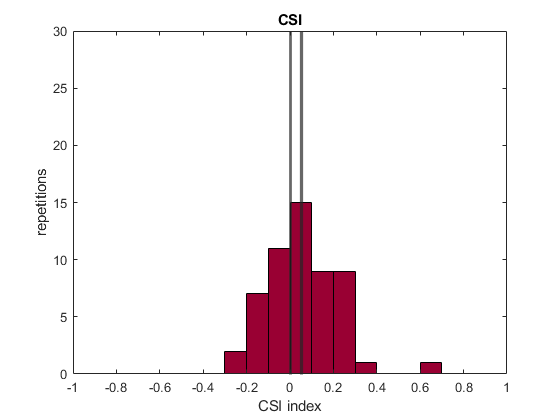

xline(CSI_Mean,'LineWidth',2.5);

%Save figure
cd 'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Indexes\CA1\CSI';
saveas(gcf,'CSI.pdf');
saveas(gcf,'CSI.tif');

saveas(gcf,'CSI.fig');

% iMM
iMMcasc = cat(1,NormalizedIndexesTable.iMM1ca,NormalizedIndexesTable.iMM2cd);
figure
%Create histogram
histogram(iMMcasc,'BinWidth',0.1,'FaceColor','#EA005F','FaceAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iMM');
xlabel('iMM index');
ylabel('repetitions');

%Calculating the mean and error
iMMcasc_Mean = nanmean(iMMcasc)

iMMcasc_Mean = 0.0574

iMMcasc_std = nanstd(iMMcasc);
err_iMMcasc = iMMcasc_std / sqrt(size(iMMcasc,1))

err_iMMcasc = 0.0212

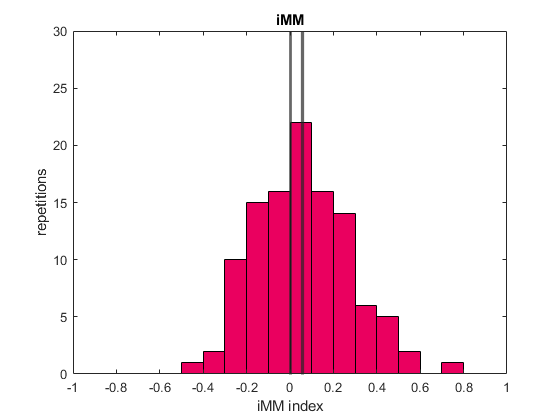

xline(iMMcasc_Mean,'LineWidth',2.5);

%Save figure
PathiMM = 'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Indexes\CA1\iMM';
cd (PathiMM);
saveas(gcf,'iMM.pdf');
saveas(gcf,'iMM.tif');

saveas(gcf,'iMM.fig');

% iPE CA1
iPEcasc = cat(1,NormalizedIndexesTable.iPE1ca,NormalizedIndexesTable.iPE2cd);
figure
%Create histogram
histogram(iPEcasc,'BinWidth',0.1,'FaceColor','#FF6600','FaceAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iPE');
xlabel('iPE index');
ylabel('repetitions');

%Calculating the mean and error
iPEcasc_Mean = nanmean(iPEcasc)

iPEcasc_Mean = 0.0270

iPEcasc_std = nanstd(iPEcasc);
err_iPEcasc = iPEcasc_std / sqrt(size(iPEcasc,1))

err_iPEcasc = 0.0260

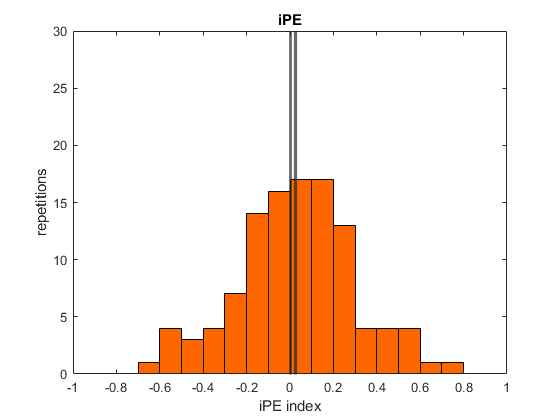

xline(iPEcasc_Mean,'LineWidth',2.5);

%Save figure
cd 'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Indexes\CA1\iPE';
saveas(gcf,'iPE.pdf');
saveas(gcf,'iPE.tif');

saveas(gcf,'iPE.fig');

% iRS CA1
iRScasc = cat(1,NormalizedIndexesTable.iRS1ca,NormalizedIndexesTable.iRS2cd);
figure
%Create histogram
histogram(iRScasc,'BinWidth',0.1,'FaceColor','#0099CC','FaceAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iRS');
xlabel('iMM index');
ylabel('repetitions');

%Calculating the mean and error
iRScasc_Mean = nanmean(iRScasc)

iRScasc_Mean = 0.0304

iRScasc_std = nanstd(iRScasc);
err_iRScasc = iRScasc_std / sqrt(size(iRScasc,1))

err_iRScasc = 0.0239

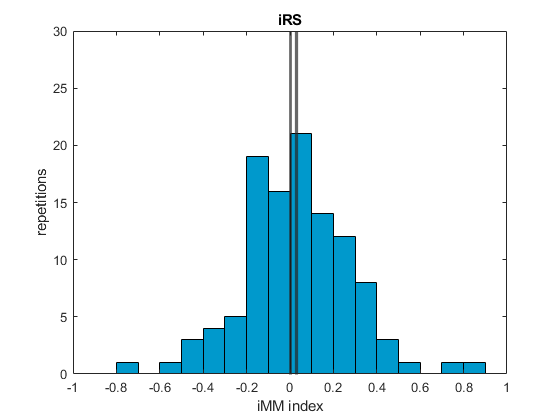

xline(iRScasc_Mean,'LineWidth',2.5);

%Save figure
cd 'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Indexes\CA1\iRS';
saveas(gcf,'iRS.pdf');
saveas(gcf,'iRS.tif');

saveas(gcf,'iRS.fig');